# HW 10

## **Problem 1 (100 points)**

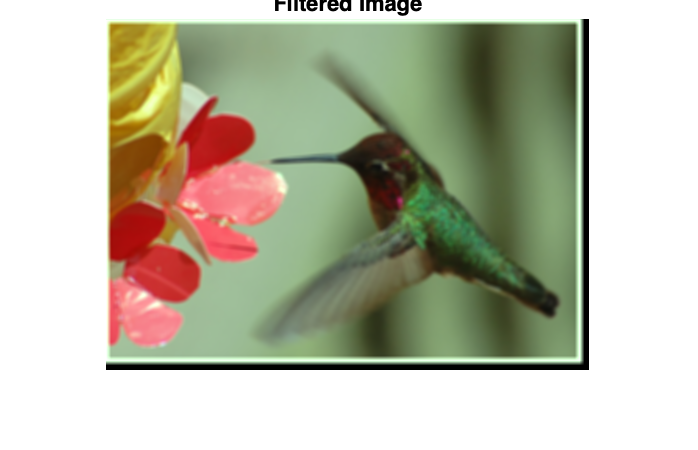

imgArray = imread("image.png");
imgRed   = imgArray(:,:,1);
imgGreen = imgArray(:,:,2);
imgBlue  = imgArray(:,:,3); 

% Some instructions are provided to help with the work flow

% create the filter f. Lets say size of the filter is m x n

% Perform padding of the original matrices
%For example
%[nrow, ncol] = size(imgRed);
%imgRed_padded = zeros(nrow+n-1,ncol+m-1);
%Update imgRed_padded to incorporate the original image into it
% Follow the process for other colors also

% get the size of the padded image/matrix. You will need it for following
% operation. 

% Initialize the filtered img with zeros, what is the size?
% imgRed_filtered = zeros(..., ...);
%...
%...

% Extract m x n submatrices from padded image and multiply them with m x n
% filter by using following nested for loops
% for i, 1: number of rows in original image
%   for j = 1: number of columns in original image
%       Take the m by n submatrix and multiply with m x n filter, sum the
%       elements of the resulting matrix
%       replace the (i,j) component of img_filtered with this sum
     %end
   %end

% replace the original matrices with the above obtained filtered matrices

r = size(imgRed, 1);
c = size(imgRed, 2);
filter(1:5,1:5) = 0.04;
class(filter);
rgb_val = {imgBlue, imgGreen, imgRed};
% This loop created the padding filter effect by maniputlating the img
% matrix 
for k = 1:numel(rgb_val)
    colorval = rgb_val{k};
    colorval = [colorval, zeros(size(colorval,1),size(filter,2)-1)];
    colorval = [colorval; zeros(size(filter,1)-1,size(colorval,2))];
    rgb_val{k} = colorval;
end
imgBlue = rgb_val{1};
imgGreen = rgb_val{2};
imgRed = rgb_val{3};

for i = 1:r
    for j = 1:c
        b = imgBlue(i:i+4, j:j+4);
        g = imgGreen(i:i+4, j:j+4);
        r = imgRed(i:i+4, j:j+4);
        imgBlue(i,j) = sum(sum(double(b) .* filter));
        %applying image greeing
        imgGreen(i,j) = sum(sum(double(g) .* filter * 1.2));
        imgRed(i,j) = sum(sum(double(r) .* filter));
    end
end
%using that loop, you can apply any "filter" based on rgb of sets
% The following code combines the three color filtered matrices and displays the
% resulting image
clear imgArray
imgArray(:, :, 1) = imgRed; imgArray(:, :, 2) = imgGreen; imgArray(:, :, 3) = imgBlue;
imshow(uint8(imgArray));
title('Filtered Image')

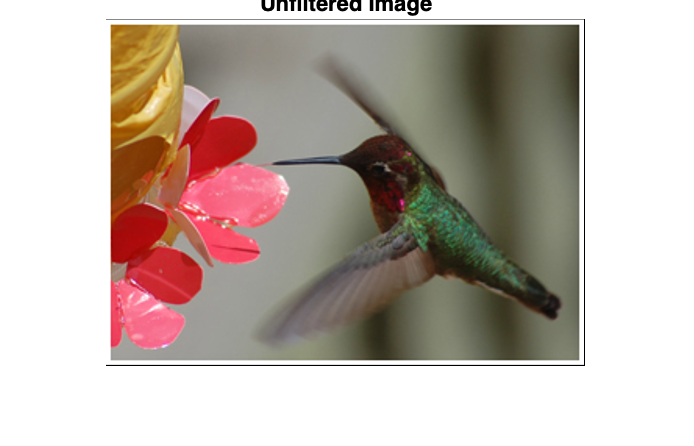

imageFilePath = 'image.png';
img = imread(imageFilePath);
imshow(img);
title('Unfiltered Image')